# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_dgm.mlx
    ---------------
    This code solves the deterministic growth model using value function iteration.

%}

## Model: Deterministic Growth Model.

## (a) to (g)

clc
clear
close all

%id = getenv('USERNAME'); % Gets your username.

main = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Deterministic Growth\Matlab"); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Deterministic Growth\Matlab 



clear;
clc;
close all;

fprintf('============== Life Cycle Model Simulation ==============\n\n')

============== Life Cycle Model Simulation ==============



%% Set up model parameters
fprintf('Setting up model parameters...\n')

Setting up model parameters...


par = model.setup();
par = model.gen_grids(par);

fprintf('Model Setup Complete:\n')

Model Setup Complete:


%% Solve model (backward iteration)
sol = solve.grow(par);

------------ Solving Life Cycle Model Backward ------------

Solving for period 4...
Solving for period 3...
Solving for period 2...
Solving for period 1...
------------ Solution Completed ------------


%% Simulate lifecycle
sim = simulate.grow(par, sol);

%% Display results in table format
fprintf('\nLife Cycle Results:\n')


Life Cycle Results:


results_table = table((1:par.T)', sim.a, sim.c, sim.y, ...
    'VariableNames', {'Age', 'Assets', 'Consumption', 'Income'});
disp(results_table)

    Age    Assets    Consumption    Income
    ___    ______    ___________    ______

     1          5      6.8863         10  
     2     9.6321      6.9722          3  
     3     6.9231       7.203          3  
     4     3.7124      7.3836          3  



%% Plot results
fprintf('\nPlotting results...\n')


Plotting results...


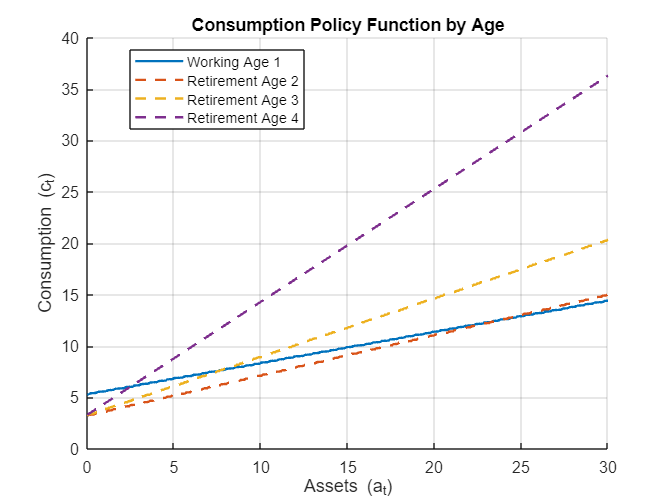

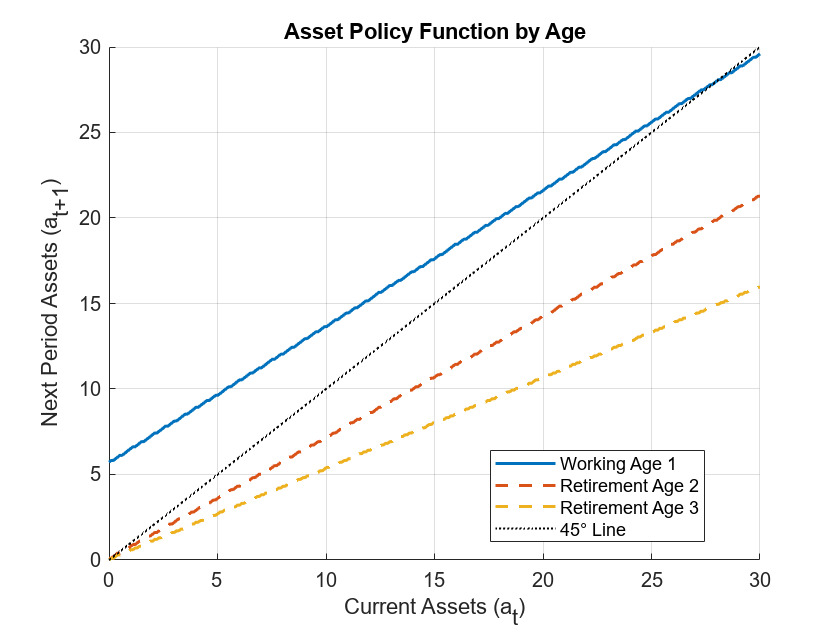

my_graph.plot_policy(par, sol);

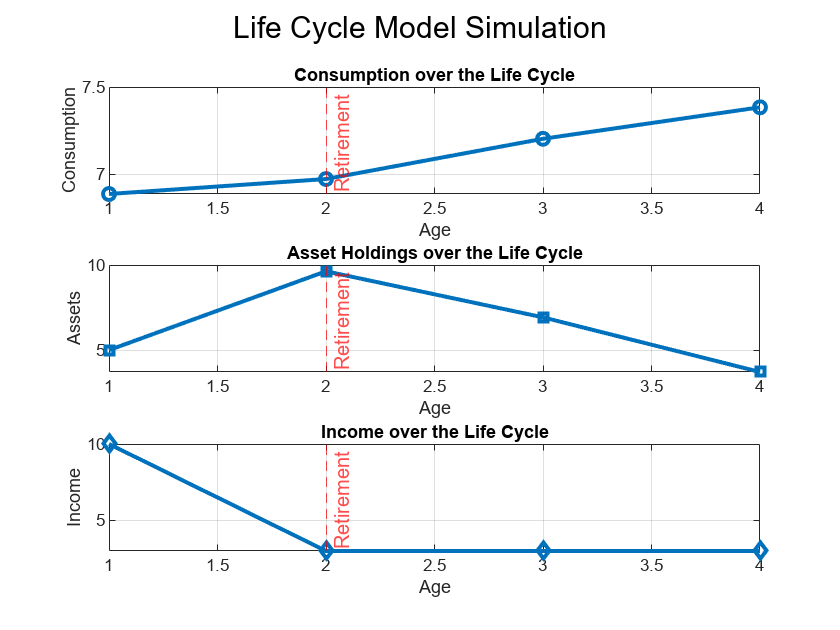

my_graph.plot_lifecycle(par, sim);

fprintf('\n============== Simulation Complete ==============\n')


============== Simulation Complete ==============


## (h) to (j)

%% Main script for Stochastic Life Cycle Model

% Clear workspace
clear;
clc;
close all;

fprintf('============== Stochastic Life Cycle Model Simulation ==============\n\n')

============== Stochastic Life Cycle Model Simulation ==============



%% Set up model parameters
fprintf('Setting up model parameters...\n')

Setting up model parameters...


par = model2.setup();
par = model2.gen_grids(par);

Income grid created with 7 states
Income states: [0.17, 0.27, ..., 2.68]


fprintf('Model Setup Complete:\n')

Model Setup Complete:


%% Solve model (backward iteration)
sol = solve2.grow(par);

------------ Solving Stochastic Life Cycle Model Backward ------------

Solving for period 3...
Solving for period 2...
Solving for period 1...
------------ Solution Completed ------------


%% Simulate lifecycle
sim = simulate2.grow(par, sol);

%% Display results in table format
fprintf('\nLife Cycle Results (First 10 periods):\n')


Life Cycle Results (First 10 periods):


periods_to_show = min(10, par.T);
results_table = table((1:periods_to_show)', sim.a(1:periods_to_show), ...
                      sim.c(1:periods_to_show), sim.y(1:periods_to_show), ...
                      sim.s(1:periods_to_show), ...
                      'VariableNames', {'Age', 'Assets', 'Consumption', 'Income', 'IncomeState'});
disp(results_table)

    Age    Assets    Consumption    Income     IncomeState
    ___    ______    ___________    _______    ___________

     1          5      1.6915       0.17107         1     
     2     3.9967      1.7437       0.05132         1     
     3      2.709       1.732       0.05132         1     
     4     1.3043      1.7648       0.05132         1     



%% Plot results
fprintf('\nPlotting results...\n')


Plotting results...


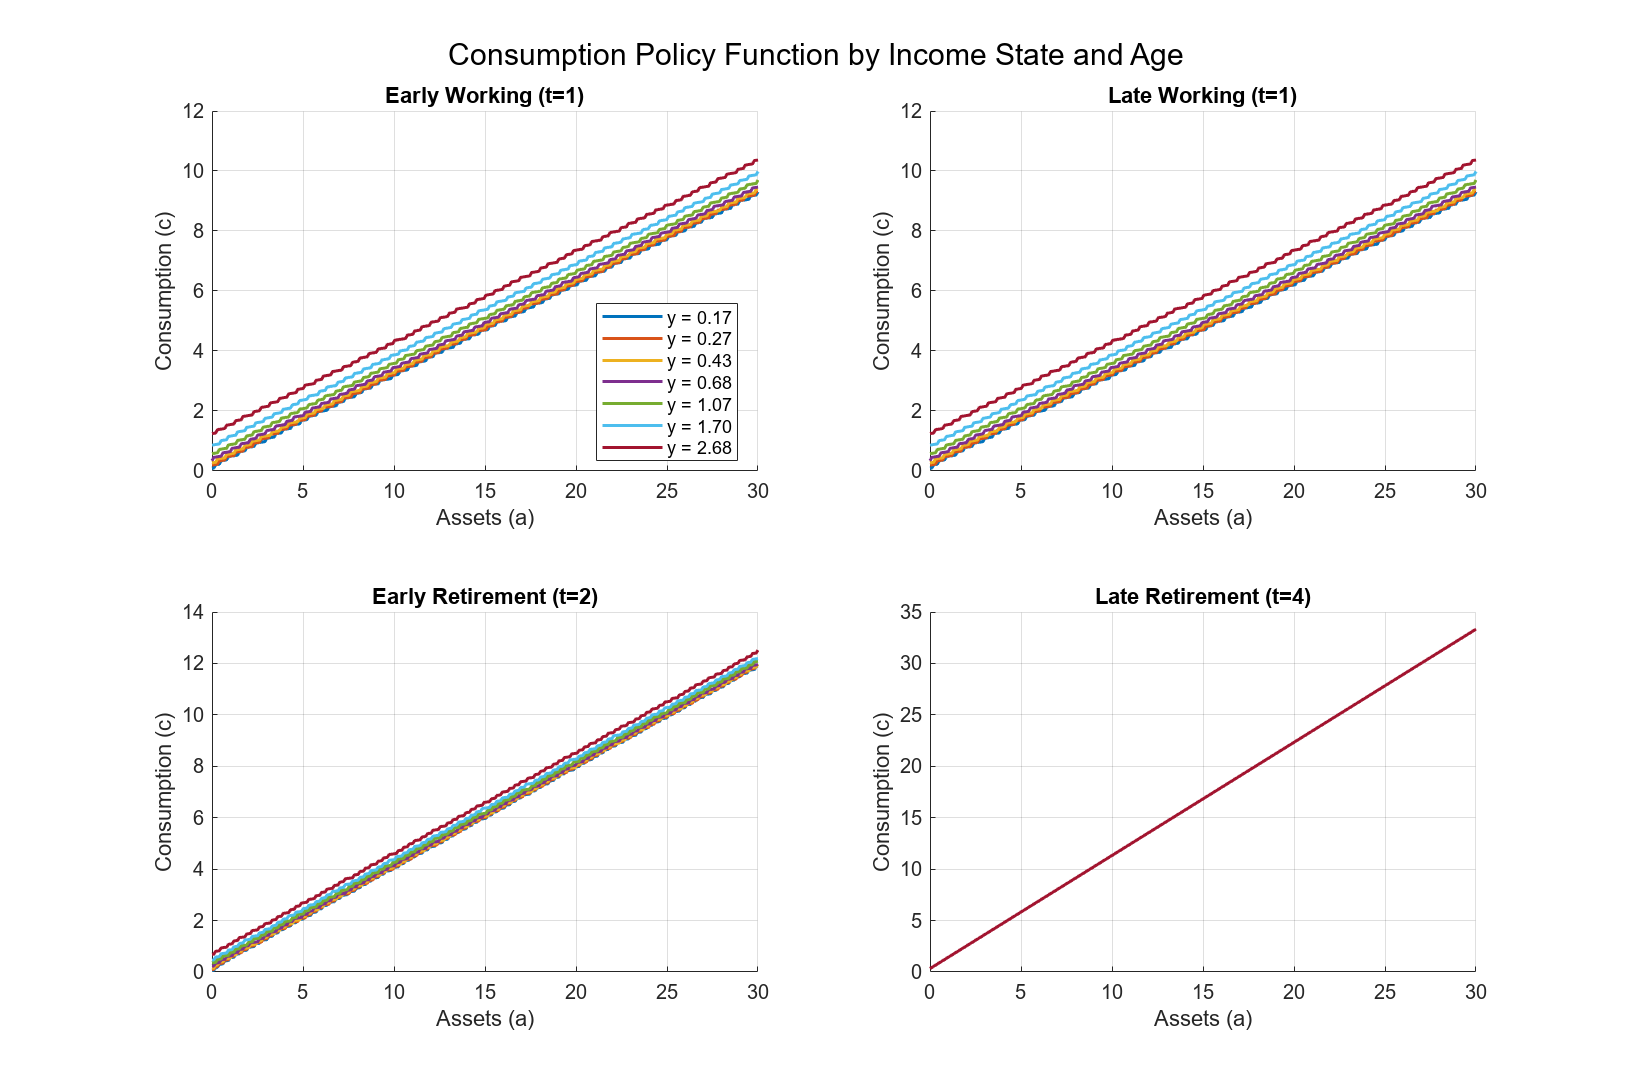

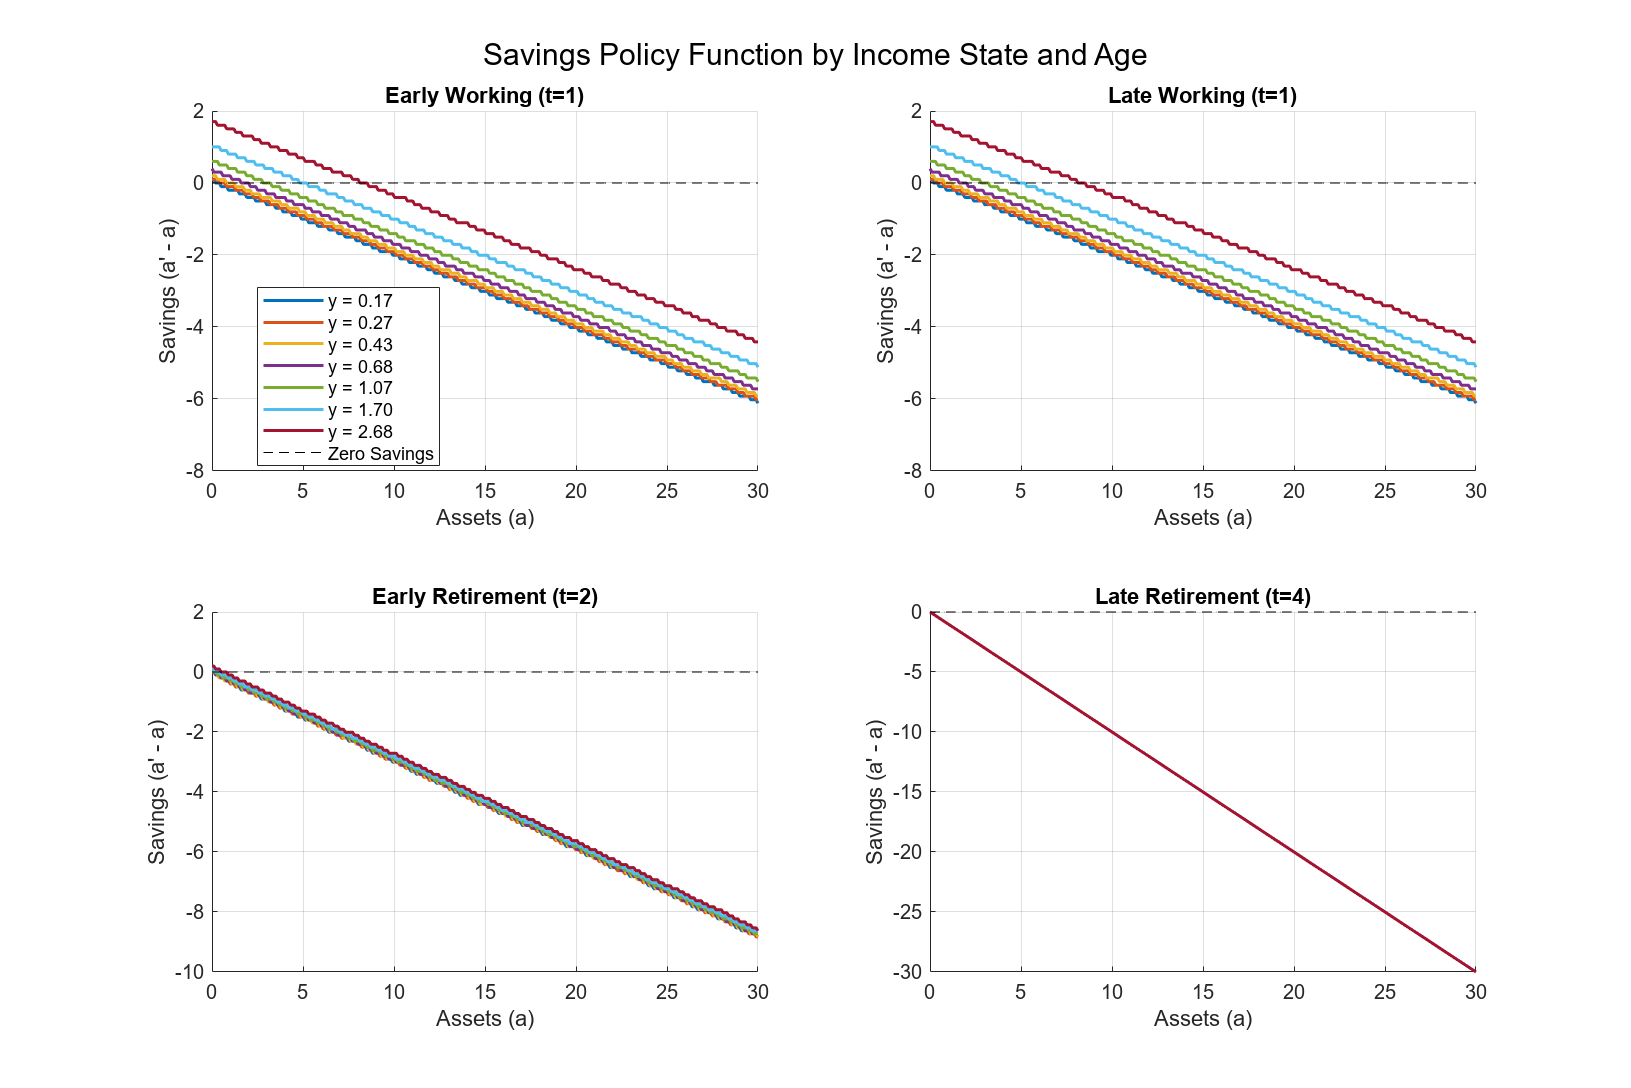

my_graph2.plot_policy(par, sol);

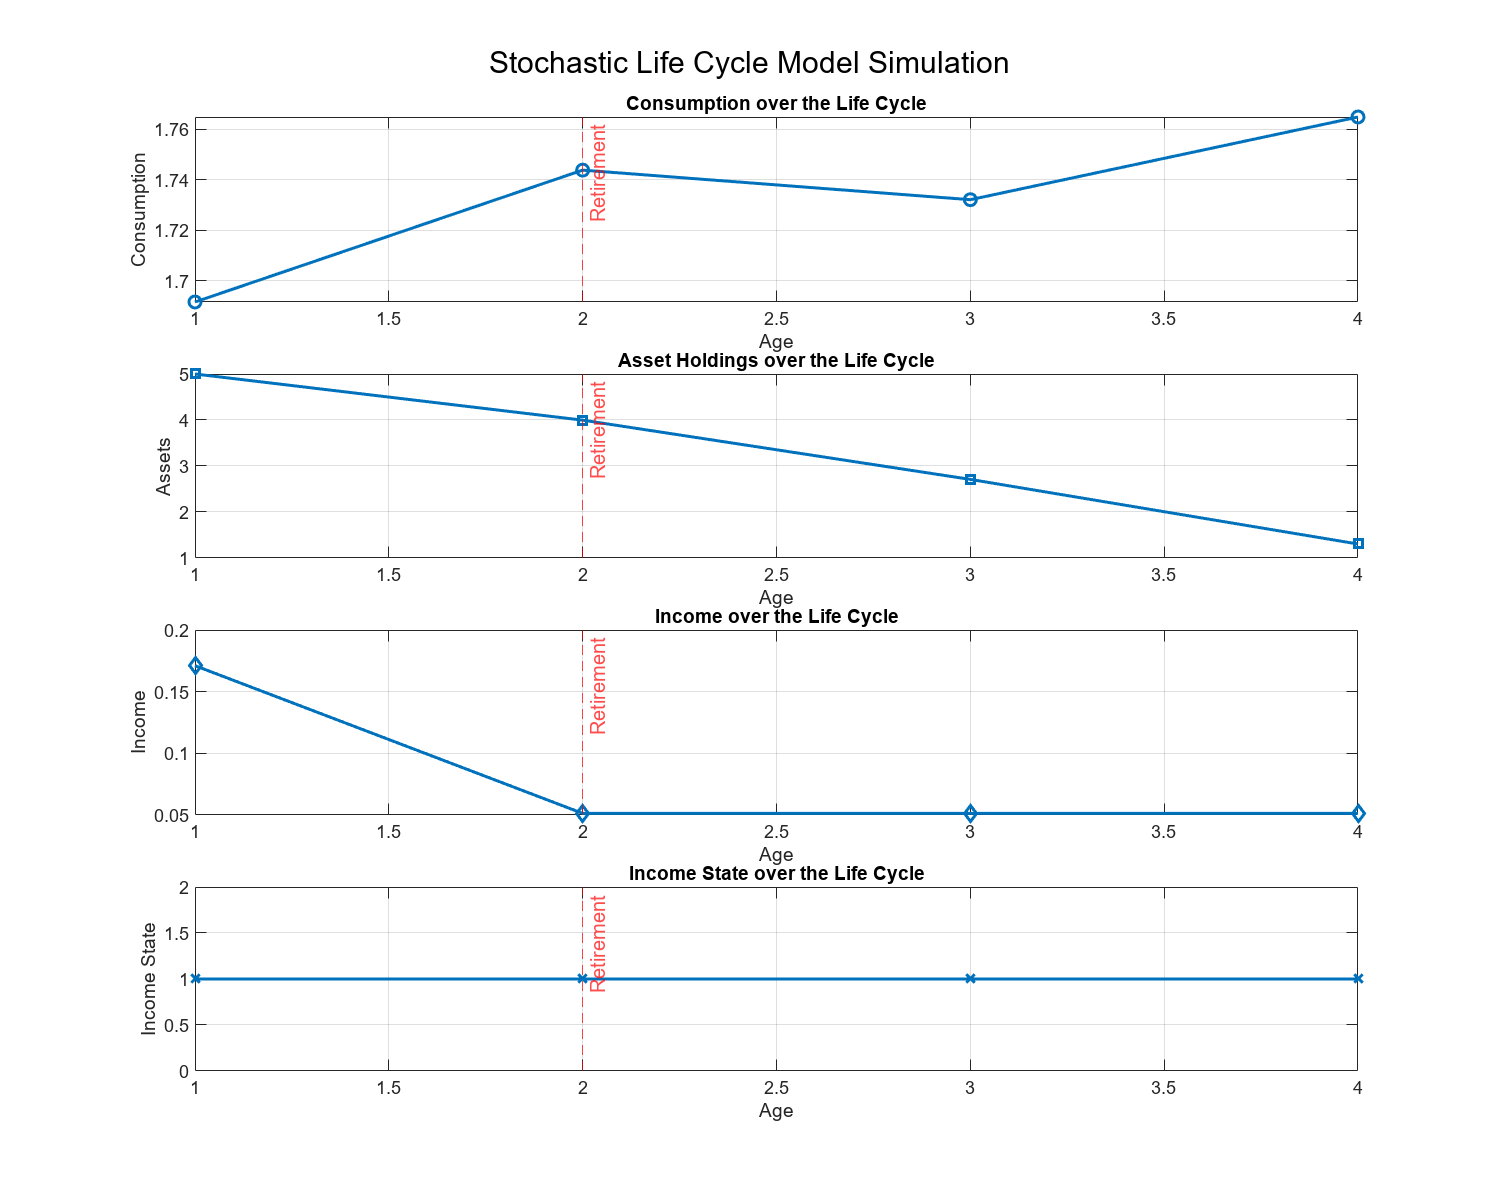

my_graph2.plot_lifecycle(par, sim);

% Define income state interpretation
% Find middle period for interpretation (a working period)
mid_work_period = min(par.tr-1, floor(par.T/2));
state_example = sim.s(mid_work_period);
income_example = sim.y(mid_work_period);

% Print interpretation
fprintf('The income state of %d implies that the agent has income of %.2f in period %d\n', ...
    state_example, income_example, mid_work_period);

The income state of 1 implies that the agent has income of 0.17 in period 1


fprintf('Income states range from 1 (lowest income = %.2f) to %d (highest income = %.2f)\n', ...
    par.ygrid(1), par.ylen, par.ygrid(end));

Income states range from 1 (lowest income = 0.17) to 7 (highest income = 2.68)


% Additional interpretation of income dynamics
fprintf('Income follows a Markov process during working years with persistence parameter rho = %.2f\n', par.rho);

Income follows a Markov process during working years with persistence parameter rho = 0.90


fprintf('After retirement (period %d), income becomes deterministic at %.2f%% of final working income\n', ...
    par.tr, par.kappa*100);

After retirement (period 2), income becomes deterministic at 30.00% of final working income


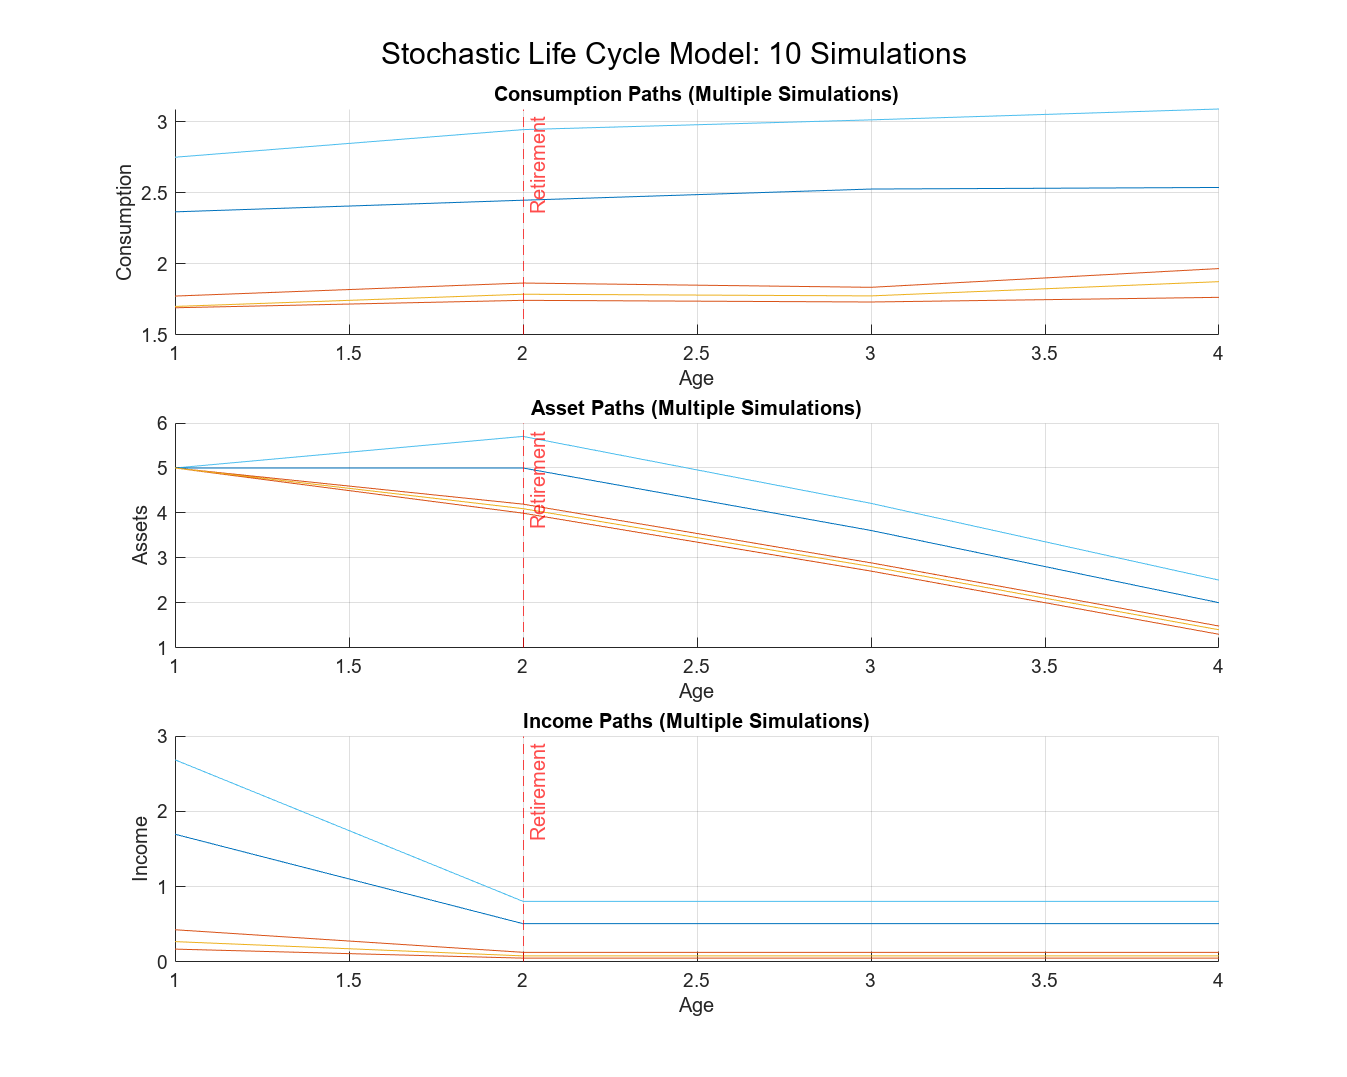

%% Run multiple simulations to show range of outcomes
n_sims = 10;
all_sims = cell(n_sims, 1);

for i = 1:n_sims
    par.seed = par.seed + i;  % Change seed for each simulation
    all_sims{i} = simulate2.grow(par, sol);
end

my_graph2.plot_multi_lifecycle(par, all_sims, n_sims);

fprintf('\n============== Simulation Complete ==============\n')


============== Simulation Complete ==============
